clear
path(path, './Optimization');
path(path, './Data');

% number of observations to make
K = 2000;

% number of spikes in the signal
Enumber = 5;

% polynomial whose coeff unknown
f = @(x)1+x+x.^2+x.^3;

X = rand(K,1)*2-1;


B = f(X);
B_corrupt = B;
B_corrupt(randperm(K,Enumber)) = (rand(Enumber,1)*2-1)*1000;

n = 3;
AN = [ones(K,1),X,X.^2,X.^3];
AL = LegendreMatrix(X,n);
polyCoeff_normal = l1decode_pd(rand(n+1,1), AN, [], B, 1e-3);
polyCoeff_legendre = l1decode_pd(rand(n+1,1), AL, [], B_corrupt, 1e-3);
clf
scatter(X,legendreval(polyCoeff_legendre,X))
hold on
scatter(X,polyval(flipud(polyCoeff_normal),X),'.')
fplot(f,[-1,1],'k')
l = legend('Legendre','x^k','sin(x)');
l.set('Location','northwest')

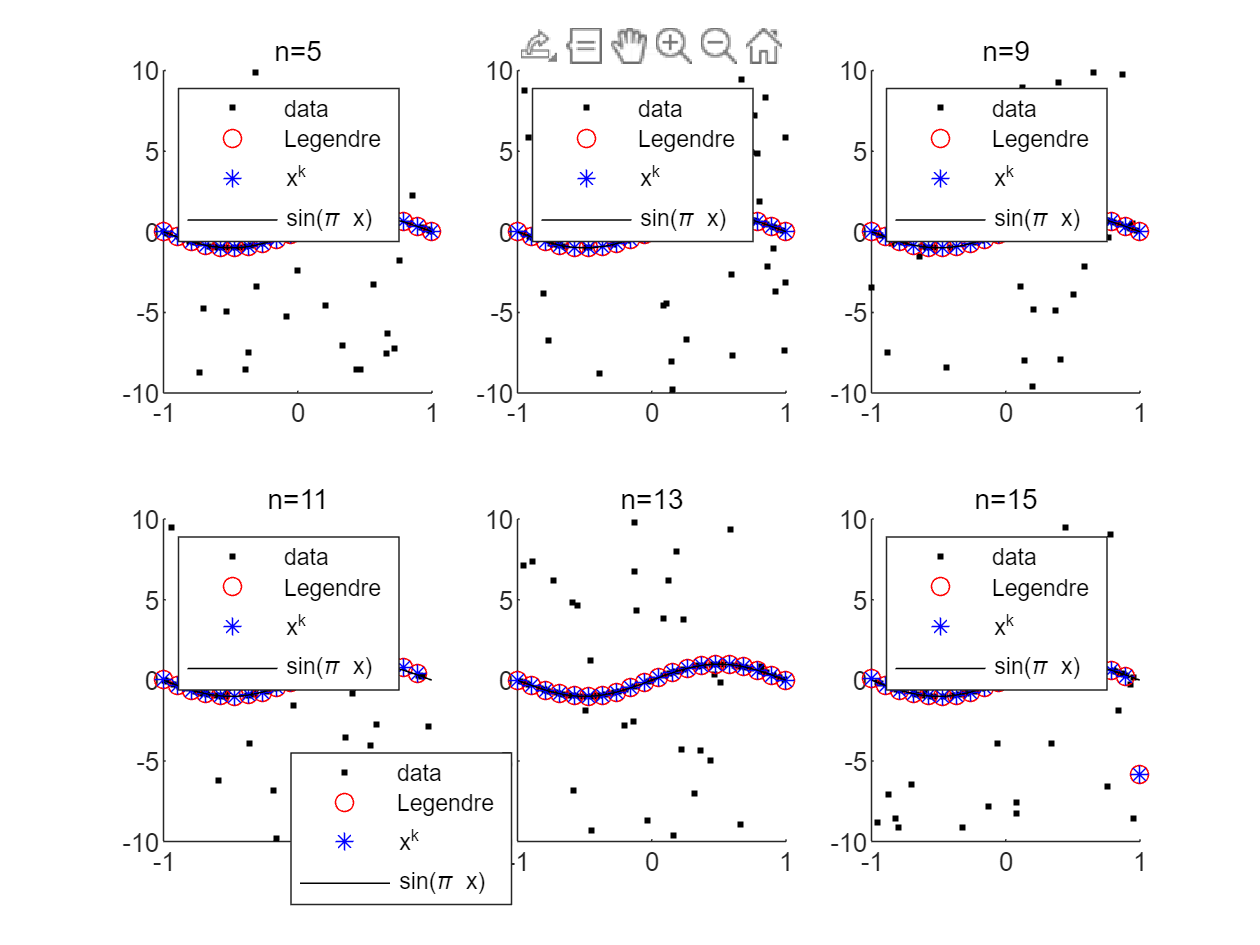

Iteration = 1, tau = 1.620e+01, Primal = 2.481e+02, PDGap = 1.235e+02, Dual res = 2.171e+01
                  H11p condition number = 2.535e-02
Iteration = 2, tau = 3.817e+01, Primal = 2.065e+02, PDGap = 5.239e+01, Dual res = 6.835e+00
                  H11p condition number = 3.684e-02
Iteration = 3, tau = 2.052e+02, Primal = 1.756e+02, PDGap = 9.747e+00, Dual res = 6.835e-02
                  H11p condition number = 4.684e-02
Iteration = 4, tau = 1.861e+03, Primal = 1.678e+02, PDGap = 1.074e+00, Dual res = 6.835e-04
                  H11p condition number = 4.862e-02
Iteration = 5, tau = 4.456e+03, Primal = 1.673e+02, PDGap = 4.488e-01, Dual res = 2.413e-04
                  H11p condition number = 5.312e-02
Iteration = 6, tau = 1.400e+04, Primal = 1.671e+02, PDGap = 1.429e-01, Dual res = 5.853e-05
                  H11p condition number = 4.254e-02
Iteration = 7, tau = 3.631e+04, Primal = 1.671e+02, PDGap = 5.508e-02, Dual res = 1.857e-05
                  H11p condition number = 3.

%% for sin x
clf
for k = 1:6
    compareSin(k)
end

function Coeff = LegendreCoeff(n)
if n == 0
    Coeff = [sym(1)];
elseif n == 1
    Coeff = [sym(0);sym(1)];
else
    Coeff = ([sym(2)*sym(n-1).*LegendreCoeff(sym(n)-sym(1))./sym(n);sym(0)]-[sym(0);sym(0);sym((n)-sym(1)).*LegendreCoeff(sym(n)-sym(2))./sym(n)]);
end
    Coeff = Coeff/sqrt(sym(2)/(sym(n)*sym(2)+sym(1)));
end

function y = legendreval(p,x)
    n = length(p)-1;
    y = zeros(size(x));
    for k = 0:n
    y = p(k+1).*legendreP(k,x) + y;
    end
end

function Matrix = LegendreMatrix(X,n)
Matrix = zeros(length(X),n+1);
for k = 0:n
    % Matrix(:,k+1)=Lerandeval(X,k);
    Matrix(:,k+1) = legendreP(k,X);
end
end

function Matrix = normalMatrix(X,n)
    Matrix = zeros(length(X),n+1);
for k = 0:n
    Matrix(:,k+1)=X.^k;
end
end

function compareSin(k)
K = 100;
n = 2*k+3;
% number of spikes in the signal
Enumber = 30;

X = rand(K,1)*2-1;%random samples
AL = LegendreMatrix(X,n);
AN = normalMatrix(X,n);
B = sin(pi*X);
B_corrupt = B;
B_corrupt(randperm(K,Enumber)) = (rand(Enumber,1)*2-1)*10;
polyCoeff_legendre = l1decode_pd(rand(n+1,1), AL, [], B_corrupt, 1e-3);
polyCoeff_normal = l1decode_pd(rand(n+1,1), AN, [], B_corrupt, 1e-3);

X0 = linspace(-1,1,20);
subplot(2,3,k)
scatter(X,B_corrupt,'k.')
hold on
scatter(X0,legendreval(polyCoeff_legendre,X0),'ro')
title(sprintf('n=%d',n))
scatter(X0,polyval(flipud(polyCoeff_normal),X0),'b*')
fplot(@(x)sin(pi*x),[-1,1],'k')

l = legend('data','Legendre','x^k','sin(\pi x)');
l.set('Location','northwest')
end